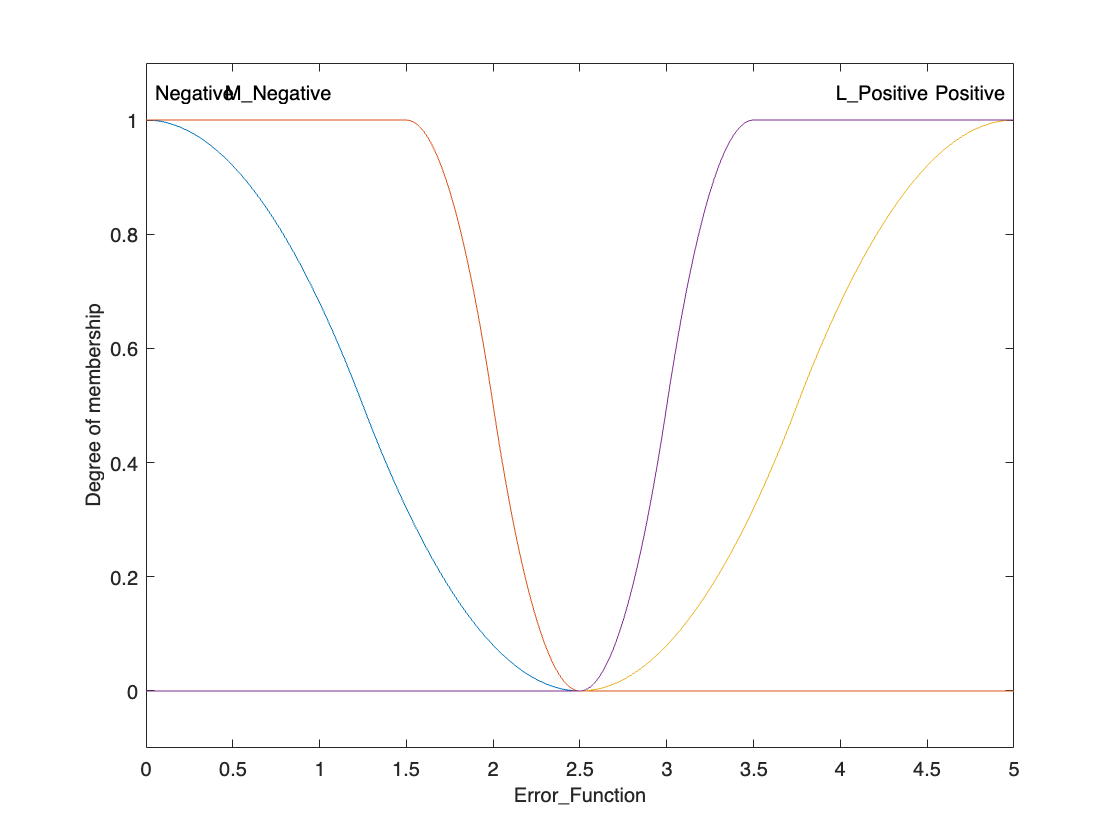

%Neurofeedback Fuzzy inference system
%% Version V2
% Authors - Mario De Los Santos, Felipe Orihuela-Espina, Javier
% Herrara-Vega, Gustavo Rodriguez 
% Date - April 27st, 2022
% Email - madlsh3517@gmail.com

cFNIRSp = mamfis(...
    'NumInputs', 1, 'NumInputMFs', 1, ...
    'NumOutputs', 1, 'NumOutputMFs', 4, ...
    'AddRule', 'none');

%Inputs

cFNIRSp.Inputs(1).Name = 'Error_Function';
cFNIRSp.Inputs(1).Range = [0, 5]; 
cFNIRSp.Inputs(1).MembershipFunctions(1).Name = 'Negative';
cFNIRSp.Inputs(1).MembershipFunctions(1).Type ='zmf'; %Z-shaped memebership function
cFNIRSp.Inputs(1).MembershipFunctions(1).Parameters = [0 2.5];

cFNIRSp.Inputs(1).MembershipFunctions(2).Name = 'M_Negative';
cFNIRSp.Inputs(1).MembershipFunctions(2).Type ='zmf'; %Z-shaped memebership function
cFNIRSp.Inputs(1).MembershipFunctions(2).Parameters = [1.5 2.5];

cFNIRSp.Inputs(1).MembershipFunctions(4).Name = 'L_Positive';
cFNIRSp.Inputs(1).MembershipFunctions(4).Type ='smf'; %S-shaped memebersh
cFNIRSp.Inputs(1).MembershipFunctions(4).Parameters = [2.5 3.5];

cFNIRSp.Inputs(1).MembershipFunctions(3).Name = 'Positive';
cFNIRSp.Inputs(1).MembershipFunctions(3).Type ='smf'; %S-shaped memebersh
cFNIRSp.Inputs(1).MembershipFunctions(3).Parameters = [2.5 5];


plotmf(cFNIRSp, 'input', 1, 1000);

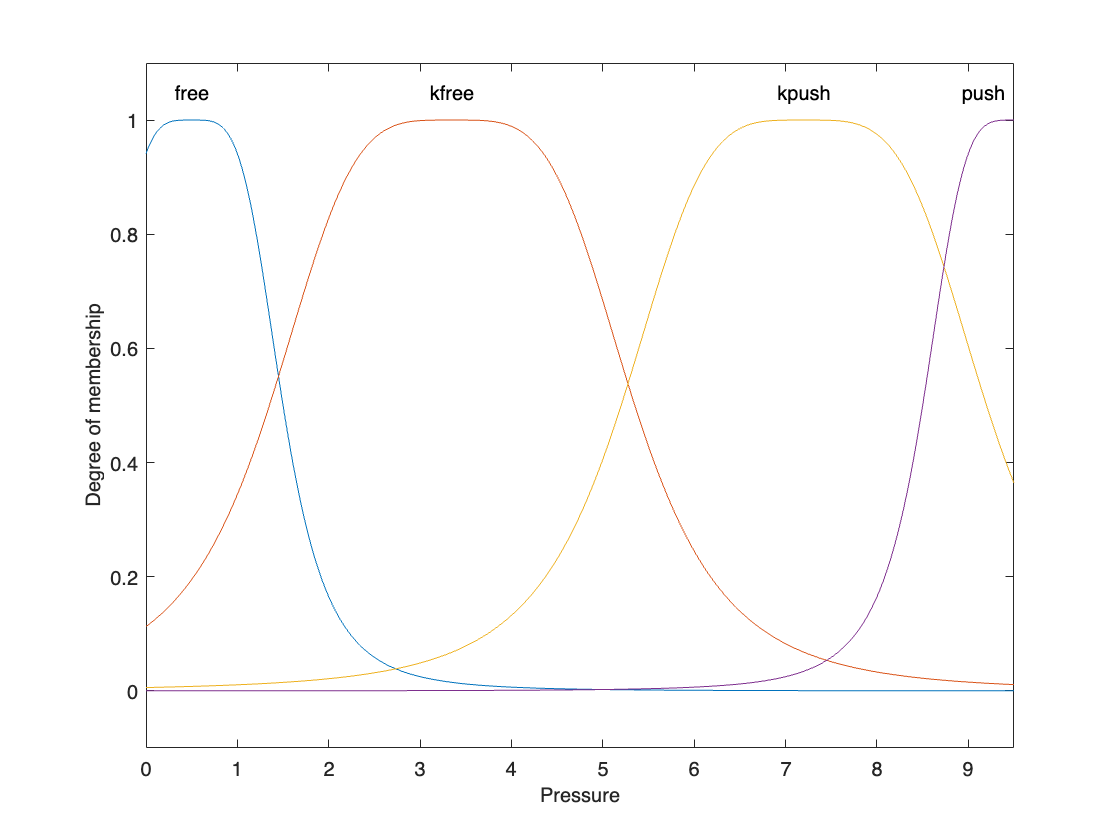




% Outputs
cFNIRSp.Outputs(1).Name = 'Pressure';
cFNIRSp.Outputs(1).Range = [0,9.5];

cFNIRSp.Outputs(1).MembershipFunctions(1).Name = 'free'; %Negative Low alternative
cFNIRSp.Outputs(1).MembershipFunctions(1).Type = 'gbellmf'; %Generalized bell-shaped membership function
cFNIRSp.Outputs(1).MembershipFunctions(1).Parameters = [1,2,0.5];

cFNIRSp.Outputs(1).MembershipFunctions(2).Name = 'kfree'; %Negative Low alternative
cFNIRSp.Outputs(1).MembershipFunctions(2).Type = 'gbellmf'; %Generalized bell-shaped membership function
cFNIRSp.Outputs(1).MembershipFunctions(2).Parameters = [2,2,3.35];

cFNIRSp.Outputs(1).MembershipFunctions(3).Name = 'kpush'; %Negative Low alternative
cFNIRSp.Outputs(1).MembershipFunctions(3).Type = 'gbellmf'; %Generalized bell-shaped membership function
cFNIRSp.Outputs(1).MembershipFunctions(3).Parameters = [2,2,7.2];

cFNIRSp.Outputs(1).MembershipFunctions(4).Name = 'push'; %Negative Low alternative
cFNIRSp.Outputs(1).MembershipFunctions(4).Type = 'gbellmf'; %Generalized bell-shaped membership function
cFNIRSp.Outputs(1).MembershipFunctions(4).Parameters = [1,2,9.5];


plotmf(cFNIRSp, 'output', 1, 1000);


%rules

rules = ["If Error_Function is Positive then Pressure is free";...
         "If Error_Function is Negative then Pressure is push";...
         "If Error_Function is M_Negative then Pressure is kfree";...
         "If Error_Function is L_Positive then Pressure is kpush"];

cFNIRSp = addRule(cFNIRSp,rules);